# CA2 - SVD

In this assignment we explore the use of the singular value decomposition (SVD). The data you work with is a collection of Wikipedia articles about 40 countries and their 40 capitals written in the most commonly spoken language in the country/city. Specifically you consider the relative frequency of each character in each article which forms a n-dimensional feature space, where n is the number of different characters in all articles combined. 

clear;
close all;

### Part 1: Prepare and Visualize the Data (30%)

In this first part, your job is to load and prepare all the data, and visualize it to get a first impression of it's structure. In the Excel file "pages-metadata.xlsx" there is some metadata about all the articles. This metadata has been used to name the files holding the text contents of the articles. The text files are located in  the "pages-txt" directory. The files are called: "<category>--<language>--<name in English>.txt".

1.1) First load the contents of the Excel file (hint: [readtable](https://se.mathworks.com/help/matlab/ref/readtable.html)), which you then use to load each of the text files.

metadata = readtable("pages-metadata.xlsx");

%Number of articles
num_articles = size(metadata, 1);

% Initialize cell arrays to store article texts and labels
article_texts = cell(num_articles, 1);
article_title = cell(num_articles, 1);


% Loop over all articles to load their text contents
for i = 1:num_articles
    % Construct the filename for the text file
    category = metadata.Cat{i};
    language = metadata.Lang{i};
    name = metadata.TitleEN{i};
    filename = sprintf('pages-txt/%s--%s--%s.txt', category, language, name);
    
    % Load the text file contents into article_texts array and close
    fileID = fopen(filename);
    article_texts{i} = fscanf(fileID, '%c');
    article_title{i} = metadata.TitleEN{i};
    fclose(fileID);
    
end

1.2) Now load the text files (hint: [fscanf](https://se.mathworks.com/help/matlab/ref/fscanf.html)). For each article, you should count the frequency of each character (including ' ', ',', '.', etc.) and save the relative frequency, i.e., the frequency divided by the total length of the article (hint: [this function](https://se.mathworks.com/help/matlab/ref/histcounts.html) could be helpful, however many approaches are possible). Nb: not all characters will be present in all articles, in other words it is possible that an article has a frequency of 0 for characters (hint: [convert the characters to ints](https://se.mathworks.com/help/matlab/ref/int16.html)). In the end, your data should not include characters that are absent in all articles, i.e., the frequency of a character is 0 for all articles.

**Q: **Why is it a good idea to use the relative frequency rather than the absolute frequency of characters?

**Answer: Because some articles are longer than other, the length varies between the articles so if we took absolute it would be difficult to learn anything about the characters. So the relative frequency gives us info in the form of percentage each character in each article**

**Q: **Explain your solution in a few sentences and why you chose to do it like this.

**Answer: Started by combining all articles with a concatenate so that we could get all unique characters from all the articles, this prevents us to have any character that does not appear in out defined characterset. We then make a matrix with 80xnumber_of_unique_characters. Now we loop torugh all the articles, first we turn all characters in the indexed article into integers and use histcounts to find amount of each charactrer in the indexed article and put the relative frequency of theese characters in our character_frequency matrix. Loop until all articles are done.**


%Combine all articles and get each unique character from all of the text
all_text = cat(2, article_texts{:});

characterset = unique(all_text);

character_freq = zeros(num_articles, length(characterset)-1);


% Loop over all articles to count the character frequencies
for i = 1:num_articles
    % Convert the article text to integers
    article_int = uint32(article_texts{i});
    
    % Compute the character frequencies
    counts = histcounts(article_int, uint32(characterset));
    
    % Save the relative frequencies
    character_freq(i,:) = counts / length(article_int);
end



1.3) Now create visualizations to get an initial impression of the data. Here it is up to you! Create at least two different visualizations of that the data, or derived information, that give you some insight about the data. The visualizations should have a proper title as well as axis labels, and if applicable, a legend/colormap/etc.

**Q: **What types of visualizations did you chose and what data are you visualizing? Why did you make these choices? Did you try out different ones, and if yes which were these and why did you decide against them in the end?

**Answer: **

**Wanted to use heatmap, but due to the big amount of data, it was hard to get something usefull out of a heatmap with a 80x510 matrix, due to the area of each "square" in the heatmap was so small. I also tried exploring other visualizations but ended up using 2 barcharts in the end due to the size and dimensionality of the data.**

**Due to the dimensionality of the data we have collected now, it is hard to visualize it without doing something with the data as i learned when i tried to visualize it with the heatmap. **

**So i created two barchart visualizations based on the mean value of each character across all articles.**

**1) We can create a barchart showing the top 30 most frequent characters. From this we can learn what language or what type of written language is the most common in our data set, and how big the difference is between the top 30. We compute the mean frequency for each character across all articles to get one average value for each character and then we sort them decending.**

**2) We create a barchart where the heights of each bar corresponds to the mean value of each relative frequency over all articles. So that we can spot clusters and what type of characters are the most common and not just the top 30. **

**Q: **Which insights did you gain from your visualizations? Can you already see some structure in the data? 

**Answer: **

**From the first bar visualization we can see that not suprisingly the most common character is " " (space). But after that we can observe that the most common characters are latin letters with some cyrillic letters mixed in, so we can assume that the latin alphabet is the most common out of all the alphabets in the articles.**

**From the seccond barchart, we can see that we have a big spike at the start at at characterset(3) and know from the previous visualization that this is " " (space) we can also say that from the first visualization we can safely assume that the cluster with the highest bars are latin characters, and checking this by printing characterset(34:100) we can also see that this is correct. But what about the other clusters between 300 and 350 and between 350 and 450? By printing out characterset(300:350) and characterset(350:450) we can see that the other clusters that form are greek letters (between 300 and 350) and cyrillic letters (between 350 and 450) So from these visualizations we can see that the data is most favored towards latin characters. Then cyrillic letters and then greek letters (this is excluding characters between 0 and 34 that are symbols and numbers) in that order.**

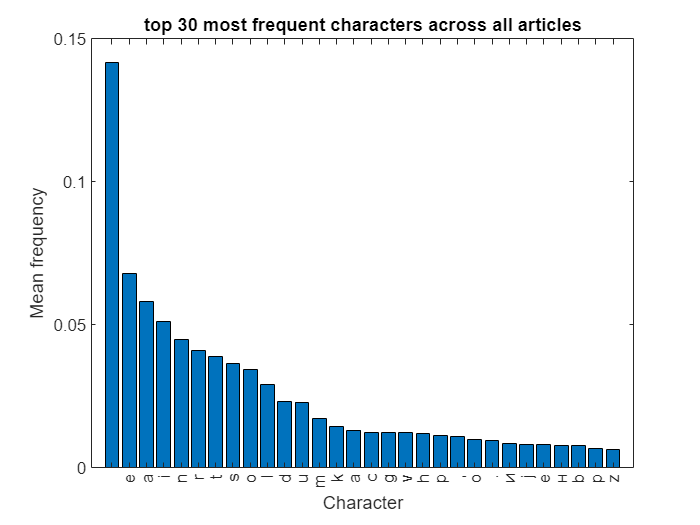

figure;
[sorted_freqs, sorted_indices] = sort(mean(character_freq, 1), 'descend');

sorted_chars = cell(30, 1);
for i = 1:30
    sorted_chars{i} = characterset(sorted_indices(i));
end

bar(1:30, sorted_freqs(1:30));
xticks(1:30)
set(gca,'xticklabel',sorted_chars)

xlabel('Character');
ylabel('Mean frequency');
title('top 30 most frequent characters across all articles');

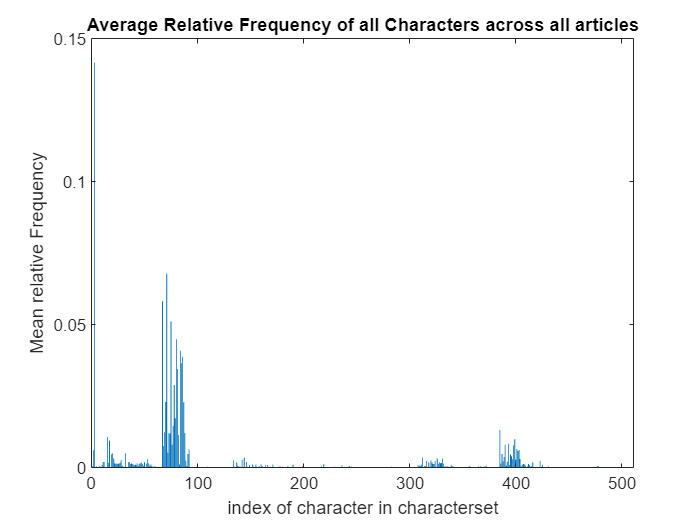


avg_freqs = mean(character_freq, 1);
% Create a bar chart of the average relative frequency of each character
figure
bar(avg_freqs)
title('Average Relative Frequency of all Characters across all articles')
xlabel('index of character in characterset')
ylabel('Mean relative Frequency')

### Part 2: SVD...(70%)

#### Part 2.1: ...of the whole data set (30%)

Now it is time to use the [SVD](https://se.mathworks.com/help/matlab/ref/double.svd.html). You can use the built-in function in Matlab, no need to do the decomposition manually. 

2.1.1) Perform the SVD.

[U,S,V] = svd(character_freq)

U =    -0.1281   -0.0173   -0.0043    0.0555   -0.0589    0.0370   -0.1321    0.0443   -0.0522    0.0521   -0.1497    0.0604   -0.0303    0.1241   -0.2014   -0.0560    0.0889    0.1186    0.0104   -0.0068    0.1452   -0.0116    0.2185   -0.1325    0.1346   -0.1085    0.1474   -0.3050    0.1347   -0.1120    0.1101   -0.1575    0.0441    0.0140   -0.0810    0.1500    0.0667    0.0660    0.1311   -0.0870   -0.1022   -0.1347    0.0905    0.0970    0.0051    0.0926    0.0310    0.2092   -0.0595   -0.1741
   -0.0525    0.2700    0.0692    0.0027    0.0037    0.0072    0.0481   -0.0511   -0.1413    0.0043    0.0029   -0.0018    0.0078   -0.0025    0.0689   -0.2959   -0.0040   -0.0066   -0.2182   -0.0810   -0.0105   -0.5143   -0.0148   -0.0263   -0.0065    0.0060   -0.0987   -0.0855   -0.0077   -0.0443    0.0041   -0.0029    0.0129    0.0334    0.1167   -0.0640   -0.0846   -0.1127   -0.0390   -0.0256    0.0053   -0.0023    0.0454    0.0572    0.0429    0.0573    0.1208   -0.0950   -0.0429    0

S =     1.9048         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0014    0.0021   -0.0016   -0.0007   -0.0019   -0.0029   -0.0001   -0.0004    0.0060    0.0083   -0.0010   -0.0056   -0.0040    0.0084    0.0176    0.0117    0.0032    0.0064   -0.0088   -0.0007   -0.0032    0.0021   -0.0054   -0.0237   -0.0434    0.0025   -0.0159    0.0037   -0.0372   -0.0160    0.0226   -0.0210   -0.0528    0.0417   -0.0354    0.0597    0.0448    0.0437    0.0612    0.0750    0.0355   -0.0393   -0.1014   -0.0616   -0.0569   -0.0337   -0.0144   -0.0167   -0.0480    0.0063
   -0.0269    0.0212   -0.0118   -0.0201    0.0451   -0.0165   -0.0429   -0.0173    0.0229   -0.0034   -0.0090   -0.0083    0.0096   -0.0102    0.0441    0.0288   -0.0153    0.0163    0.0382   -0.0002   -0.0175   -0.0398    0.0243   -0.0750   -0.2301   -0.0379   -0.2627    0.1351   -0.0736    0.0267    0.1415   -0.1984   -0.2188    0.2377   -0.1084    0.0823    0.0106    0.1131    0.1491   -0.0493   -0.1381    0.0908    0.0332    0.0270   -0.0197   -0.0935   -0.0117   -0.1067    0.0171   -0

2.1.2) To begin, you should consider the singular values. Plot these in decreasing order (i.e., plot the largest singular value at x=1, the n'th largest at x=n). Give the visualization a proper title and axis labels. 

**Q: **What do the singular values encode? How many degrees of magnitude is there between the biggest and the smallest value? What can you learn from the plot? 

**Answer: **

**What do the singular values encode?**

- **The singular values are sorted in descending order so the first few singular values capture most of the variance in the data. The singular values represent the relative amount of variation in the data that is captured by each component.**

**How many degrees of magnitude is there between the biggest and smallest value?**

- **The biggest value has a value of 1.90479 while the smallest value is 0.00161, this makes the biggest value 1183.1 times larger than the smallest value**

- **We can also see that the largest singular value is about twice as big as the next-big one**

**What can you learn from the plot?**

- **The largest singular values are much bigger than the smaler ones, this means that there is a strong lower dimensional structure to the data, so we might be able to summarixe the data using a lower dimensional subspace.**

- **We also look at the contained energies, where the more coomponents we include the closer we get to 1=100%. And can see that 78% of the data is presented by the first principal component itself! Then 89% for 2 component and 93% for 3 component.**

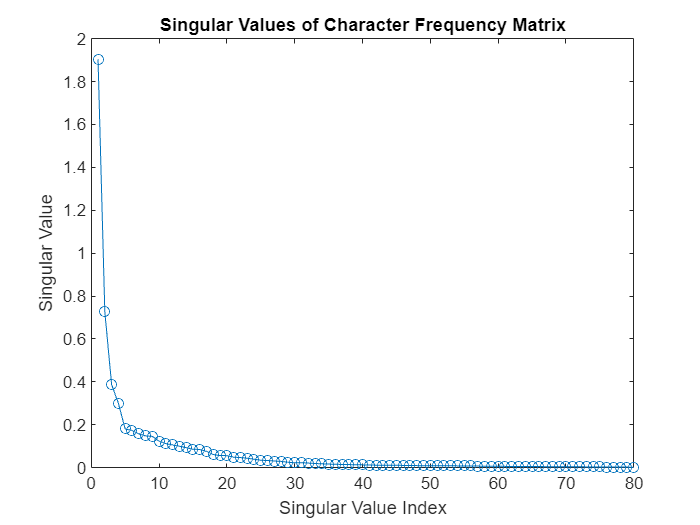

%% s is the singular values. we have 80 singular values.
figure;
plot(diag(S), 'o-')
title('Singular Values of Character Frequency Matrix');
xlabel('Singular Value Index');
ylabel('Singular Value');

%%%%%%%%energies

d = diag(S)

d =     1.9048
    0.7266
    0.3873
    0.2994
    0.1800
    0.1729
    0.1574
    0.1475
    0.1453
    0.1230


eall = d.'*d; % complete Frobenius norm

e = d(1)*d(1)/eall; 
for i = 2:80
    e = [e d(1:i).'*d(1:i)/eall];
end
e

e =     0.7836    0.8977    0.9301    0.9494    0.9564    0.9629    0.9682    0.9729    0.9775    0.9807    0.9834    0.9858    0.9880    0.9898    0.9914    0.9929    0.9941    0.9949    0.9956    0.9963    0.9968    0.9972    0.9976    0.9979    0.9982    0.9984    0.9986    0.9988    0.9989    0.9990    0.9991    0.9992    0.9993    0.9994    0.9994    0.9995    0.9995    0.9996    0.9996    0.9996    0.9997    0.9997    0.9997    0.9997    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998


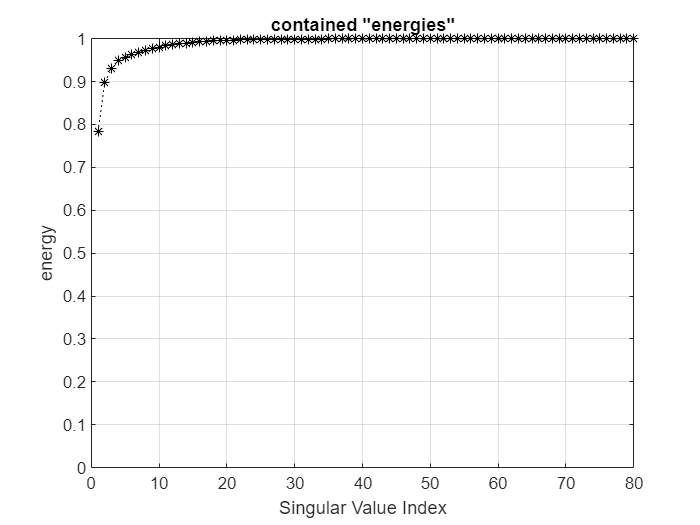

%% We look at the energies and can see that 78% of the data is presented by the first principal component itself! Then 89% for 2 component and 93% for 3 component.
figure; 
plot(e, 'k:'), grid on, hold on, plot(e, 'k*') 
plot([1 1], [0 0], 'k')% make sure that 0 is in the plot, too
title('contained "energies"')
xlabel('Singular Value Index');
ylabel('energy');

2.1.3) Next perform a rank-2, then a rank-3, approximation. Visualize the approximated data in **V**-coordinates. 

**Q: **Is there a clear structure in your data, and if yes describe it? (Can you, for example, distinguish groups?) Do you prefer the rank-2 or the rank-3 approximation, and why?

**Answer: We can see three clear grouings one big with the majority of the datapoints, one less big and one very small group with only 4 data points. Given that we have looked at the energies and now at visuializations we can see that there is not that big of a difference in rank 2 and rank 3 approximation (89% vs 93%). Because of this i would prefer rank 2, because then we have one less dimenionality to think of and its easier to work in 2d, so if we can choose a smaller dimension with out big loss of information then this is preffered. **

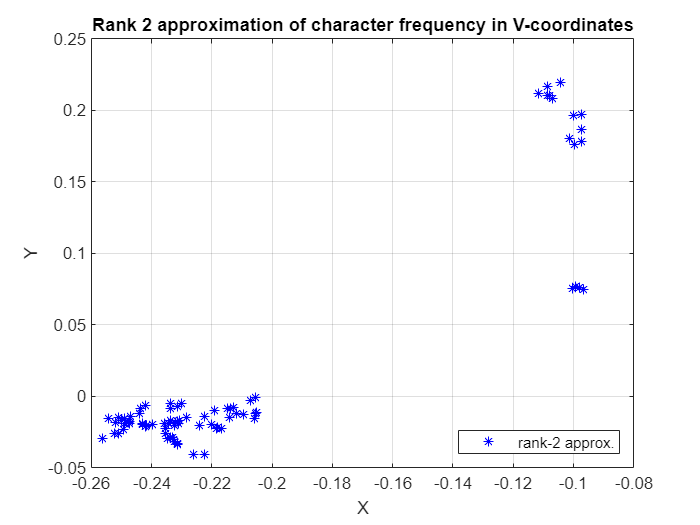

DinV = U * S; 

%RANK 1
D1 = U(:,1) * S(1,1) * V(:,1)';
D1inV = U(:,1) * S(1,1);

%RANK 2
D2 = U(:,1:2) * S(1:2,1:2) * V(:,1:2)';
D2inV = U(:,1:2) * S(1:2,1:2);
D2V = V(:,1:2)'; 

%RANK 3
D3 = U(:,1:3) * S(1:3,1:3) * V(:,1:3)';
D3inV = U(:,1:3) * S(1:3,1:3);

DinV_tit = [article_title'; num2cell(DinV)']';


figure;
format long,  
plot (D2inV(:,1), D2inV(:,2), 'b*'), grid on,
legend({'rank-2 approx.'},"Location","southeast")
title('Rank 2 approximation of character frequency in V-coordinates');
xlabel('X');
ylabel('Y');

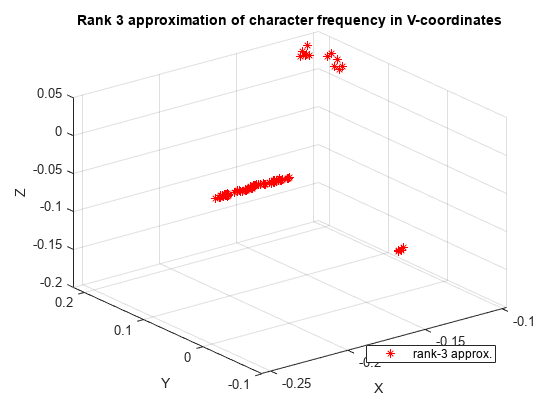

%%VISUALIZE RANK 3
figure;
scatter3(D3inV(:,1), D3inV(:,2), D3inV(:,3), 'r*')
title('Rank 3 approximation of character frequency in V-coordinates');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend({'rank-3 approx.'},"Location","southeast")

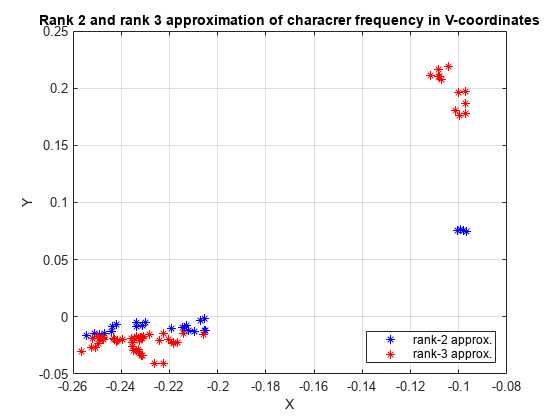

%%VISUALIZE BOTH RANK 2 AND RANK 3
figure; 
plot (D2inV(:,1), D2inV(:,2), 'b*'), hold on, grid on,
scatter3(D3inV(:,1), D3inV(:,2), D3inV(:,3), 'r*'),
legend({'rank-2 approx.','rank-3 approx.'},"Location","southeast")
title('Rank 2 and rank 3 approximation of characrer frequency in V-coordinates')
xlabel('X');
ylabel('Y');
zlabel('Z');

2.1.4) To understand the structure that can be seen, add labels to the points in your preferred approximation (rank-2 or rank-3) (hint: [add text to plots](https://se.mathworks.com/help/matlab/ref/text.html)). You do not have to label all points as this can result in a very busy plot (however, if you prefer, you can of course label all points). You can, for example, label only the countries (or only the capitals), or label only a certain number of points. What is important is that you should get an idea of how the structure in the data can be explained.

**Q: **How would you explain the structure you see in the data, based on the information from the labels?

**Answer: **

**We label all points even tough this creates a busy plot we can explore the data toroughly with matlabs interactive tools like zoom and pan. What we notice is that we can see the same pattern as we saw in the barchart where we have 3 groups, where the biggest group is contries that use latin characters, and then contries that cyrillic characrters, and lastly the small cluster with 4 data points are contries that use greek characters (Greece and Cyprus). We also see that contries and their respective capitals are plotted close together this makes sense as the wikipedia articles for contry and city is written with the same characters.**

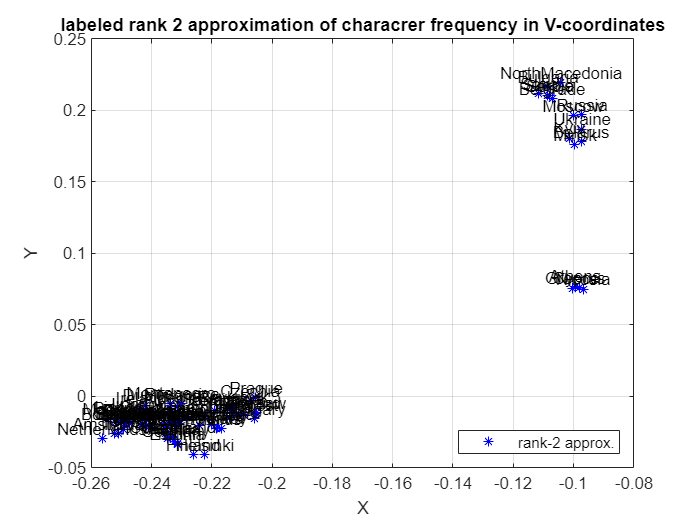

figure;
format long
plot (D2inV(:,1), D2inV(:,2), 'b*'), grid on;
for i = 1:size(D2inV, 1)
    text(D2inV(i, 1), D2inV(i, 2), article_title{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('labeled rank 2 approximation of characrer frequency in V-coordinates')
legend({'rank-2 approx.'},"Location","southeast")
xlabel('X');
ylabel('Y');

#### Part 2.2: ...of subsets (40%)

From part 2.1 you learned that the data contains clearly distinguishable groups, however, it was difficult to observe the structure of these individual groups. You will therefore perform a new SVD analysis of each of these groups seperatly. Separating out the groups can be done simply in the **V**-coordinate space of the previous SVD (hint: find a values along one of the axes that separates the groups). 

2.2.1) Separate out the groups by the logic described above. Make sure that all points are included in a group by comparing the sum the number of points in each group to the total (80).

**Q: **What were the thresholds you used to separate the groups and along which axis?

**Answer: From the figure we see three groups where we can easily split the groups once on the x axis with a value of -0.18 so that we get the data split into two, one containign the big group and the other containing the two smaller groups. We then split the two smaller groups on the y-axis with a value of 0.1 and are now left with the three groups that we want. We check the lenghts of the groups and sum them to 80 to see that we have included all data pints aswell as visualize it to make sure.**

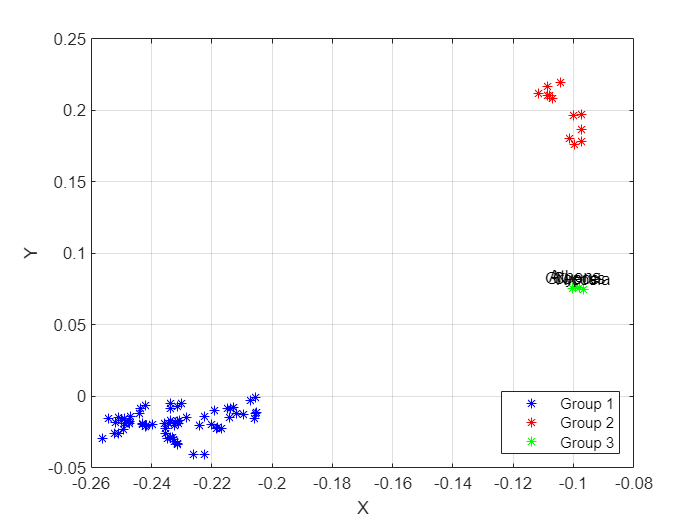

% First we split into two groups on x-axis -0.18

Group1 = DinV(DinV(:,1) < -0.18, :);
tmp = DinV(DinV(:,1) > -0.18, :);

% Then we split the group to the right by y-axis 0.1 so we are left with 3 groups
Group2 = tmp(tmp(:,2) > 0.1, :);
Group3 = tmp(tmp(:,2) < 0.1, :);

% CHECK if we include all points
assert(size(Group1,1) + size(Group2,1) + size(Group3,1) == size(character_freq, 1));

% We visualize to see if we have managed to split the 3 groups
figure;
plot (Group1(:,1), Group1(:,2), 'b*'),hold on, grid on
plot (Group2(:,1), Group2(:,2), 'r*');
plot (Group3(:,1), Group3(:,2), 'g*');
legend({'Group 1', 'Group 2', 'Group 3'},"Location","southeast")
xlabel('X');
ylabel('Y');

2.2.2) Next, do the following steps for each of the groups (note that you should answer the questions even though they are not marked explicitly with a "**Q**"):

a) Perform SVD

b) Plot the singular values (with title, axis label,..), what does this tell you?

c) Visualize a rank-2 (and rank-3) approximation of the data in **V**-coordinates and standard coordinates, including the "usual" (title, axis label,..) as well as labels for the points. Which of the plots do you prefer and why? What can you see in these plots? Are there any surprises/interesting aspects/confusing aspects? Present your insights by inserting images of interesting finds in your plots (f.ex. after zooming in on an area, rotating the 3d view, adding additional labels, etc..) (insert images by going to the **INSERT **tab and clicking "Image"), and explaining what can be seen in the images and why you find this interesting. 

**ANWSERS:**

**Plot the singular values (with title, axis label,..), what does this tell you?**

**The resulting plot will show the importance of each singular value. The decay of the singular values will give an indication of how much of the variance in the data is explained by each singular value. We can usualy see that the first singular value is much bigger than the rest, meaning this value explains most of the data.**

**Which of the plots do you prefer and why? **

- **I preffer the plots in V-coordinates because we get a bigger spread making it easier to analyse the data points and see how they relate to eachother, in standard coordinates they are too packed together making it diffigult to work with.**

**What can you see in these plots? **

- **We can get a closer look of the different groups and see similarities and differences in their relative character frequency between different contries and capitals, are the data points plotted closer together then they have similarities are they plotted futher away then we have less similarities**

**For group 1, I found a couple of interesting things:**

- **In the rank 2 approximation of group 1, we can see that at the top of the plot we can see a lot of germanic countries that are close together, and not far from that again we can see Denmark and Norway, while Sweden is a bit further away and more closely related to southern European countries.**

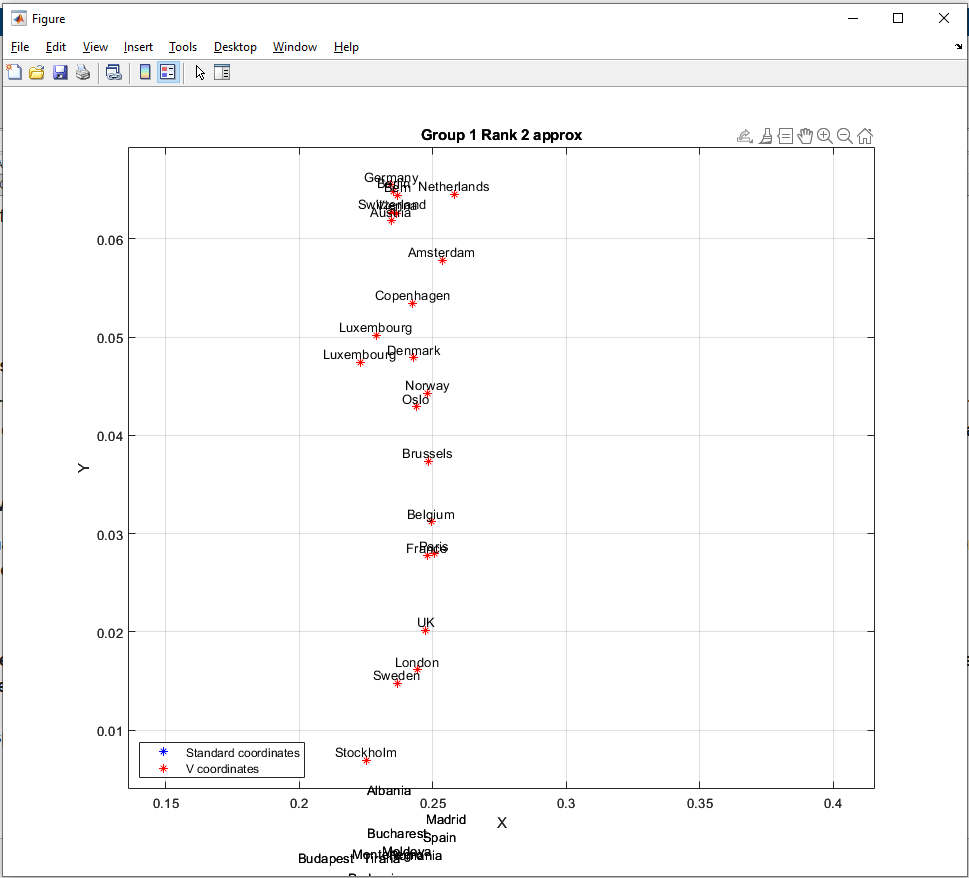

- **And if we look at the two other "Scandinavian" countries, Iceland and Finland, We can see that Iceland is more related to south-eastern European countries (like Slovenia, Slovakia, and Czechia) and that Finland is more related to south-eastern and eastern European countries (like Bosnia and Herzegovina, Croatia, and Estonia). And, surprising Ireland and Dublin, this was very unexpected due to their geographic location being so far away.**

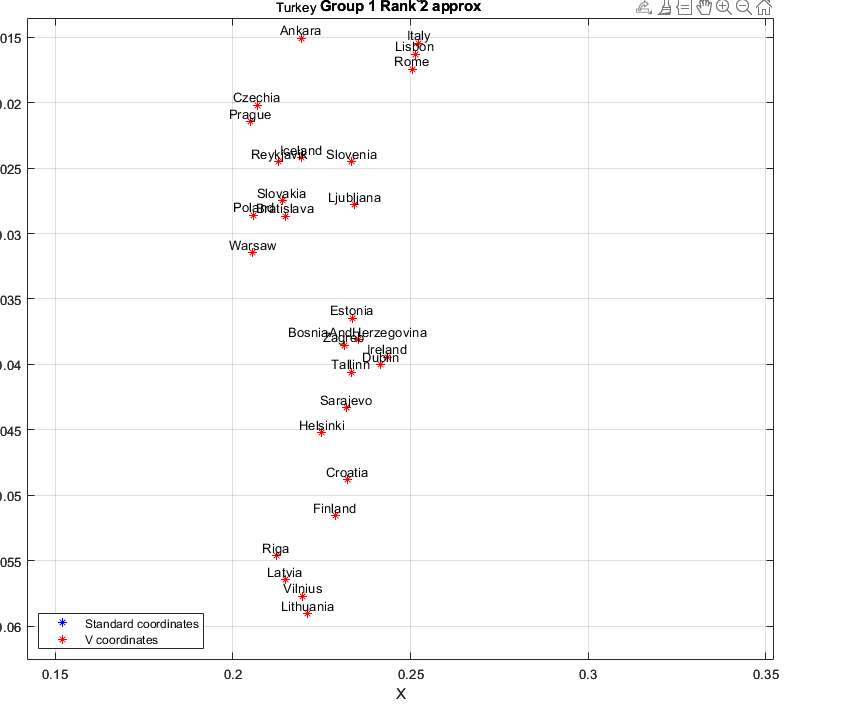

- **In the Rank 3 approximation of Group 1, something that I found interesting was that Iceland is so closely related to Turkey and Ireland. With Ireland, one can make the argument that the two countries are close, but with Turkey, it is not possible to do this. I think this discovery is the most interesting in the entire data set. We can also see that Iceland and Finland are closer related than in the rank-two approximation.**

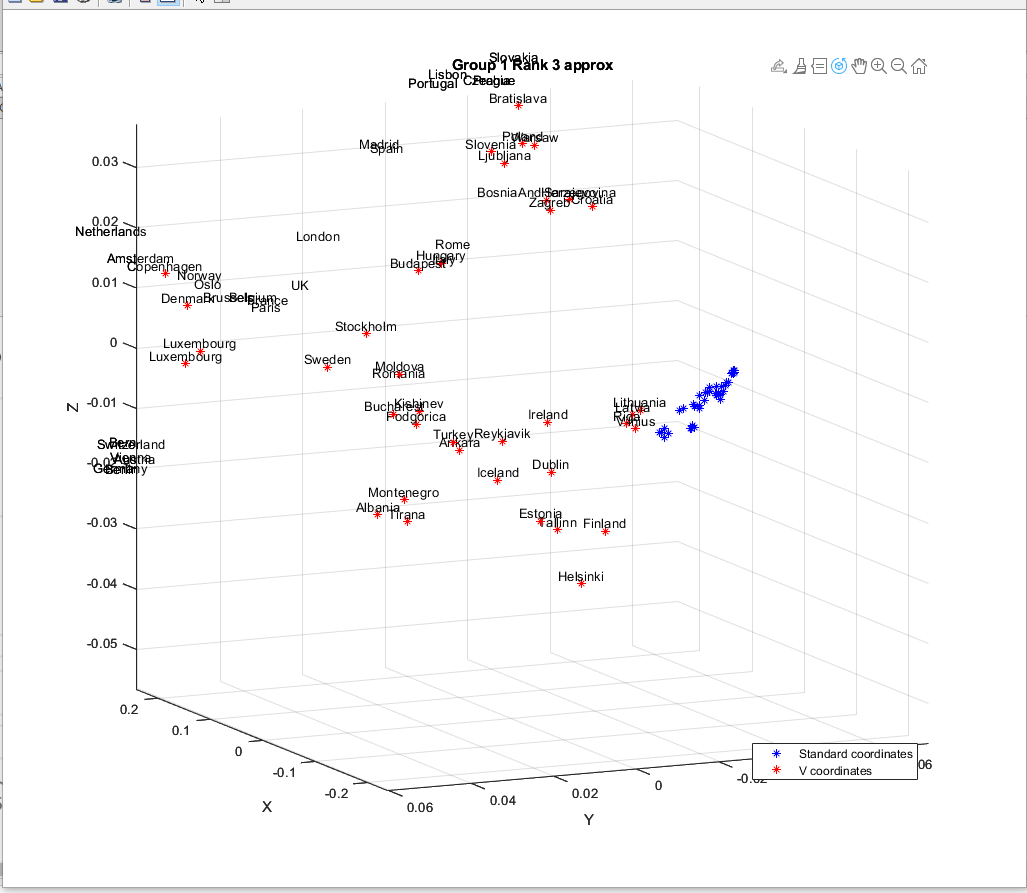

- **In the rank 2 approximation of group 2, I found it interesting that Russia is closer to Serbia, Bulgaria, and North Macedonia in character frequency than Ukraine and Belarus. I was thinking it would be the other way around due to location.**

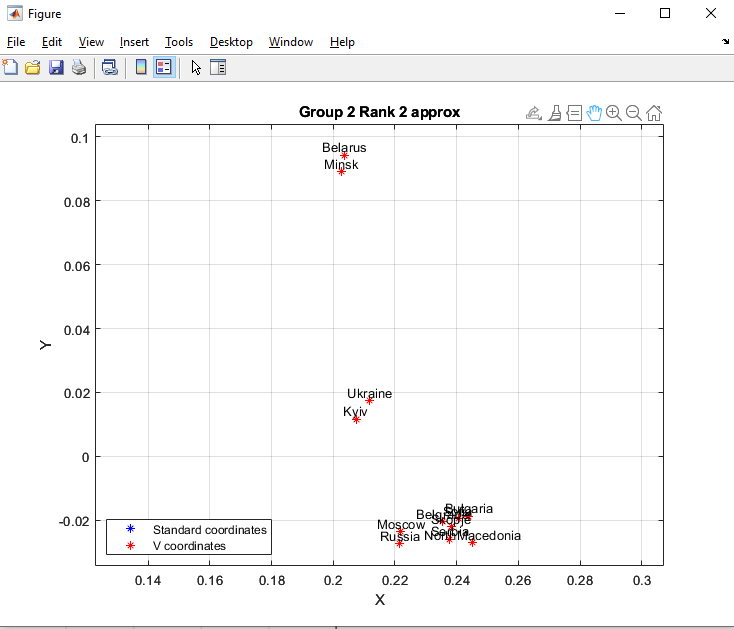

- **Now if we look at it in rank 3 approximation, we can see that Ukraine and Russia are closer, but that Belarus is still far away, so it seems that a higher approximation can in fact show crucial information at times.**

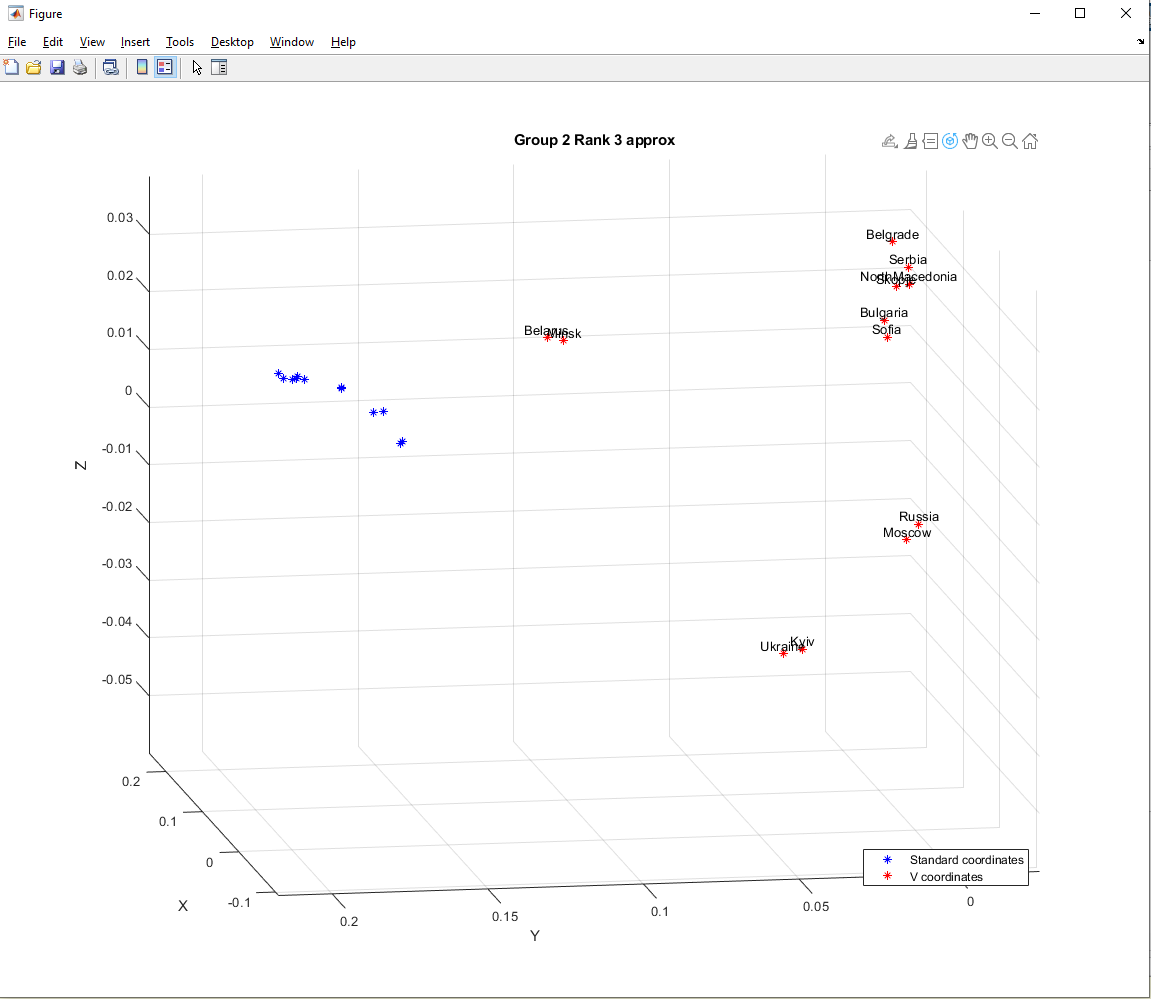

- **For Group 3, it was not really that interesting, not a big difference in rank 2 or 3, approx. An interesting fact, though, is that there is such a small group in the data set since the Greek characters are so unique to Greece and Cyprus.**

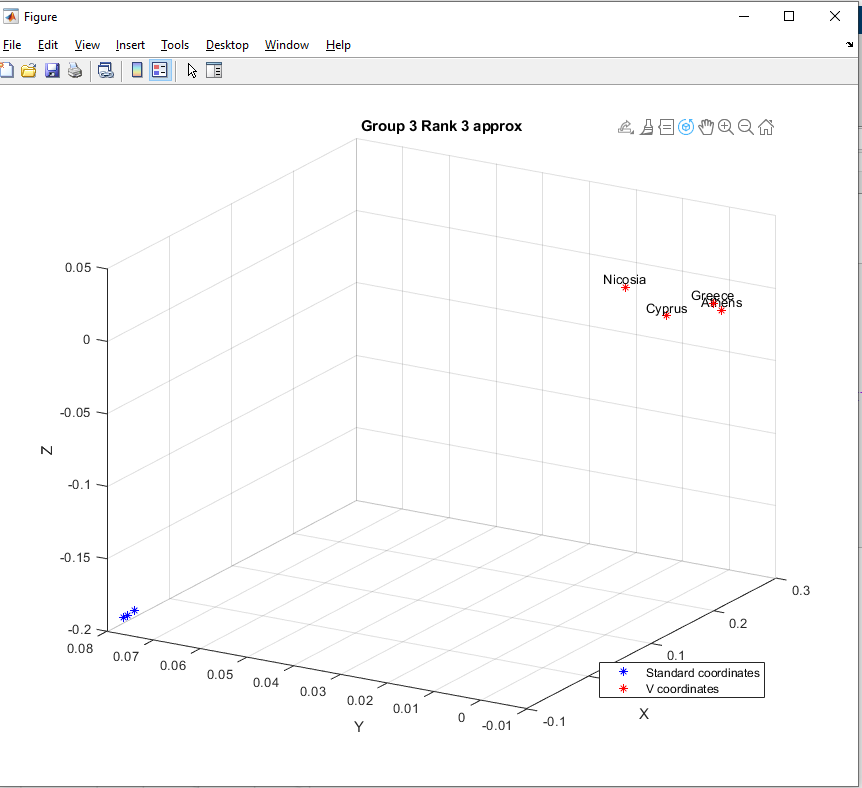

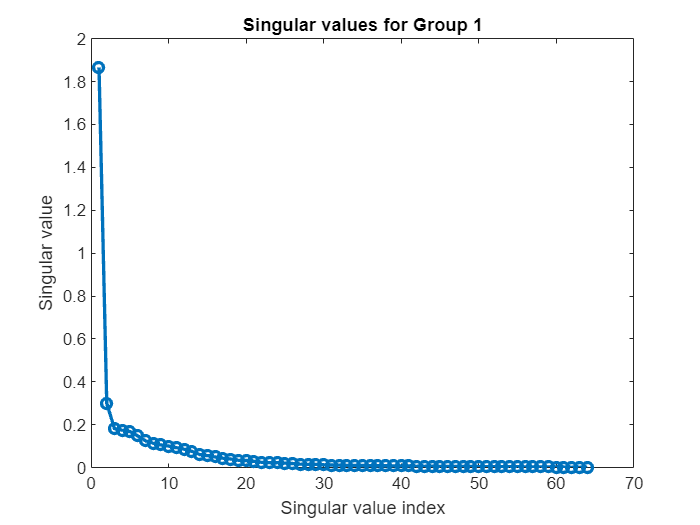

% a) / % b)

% SVD and visualization for Group 1
[U1, S1, V1] = svd(Group1);
figure;
plot(diag(S1), 'o-', 'LineWidth', 2);
title('Singular values for Group 1');
xlabel('Singular value index');
ylabel('Singular value');

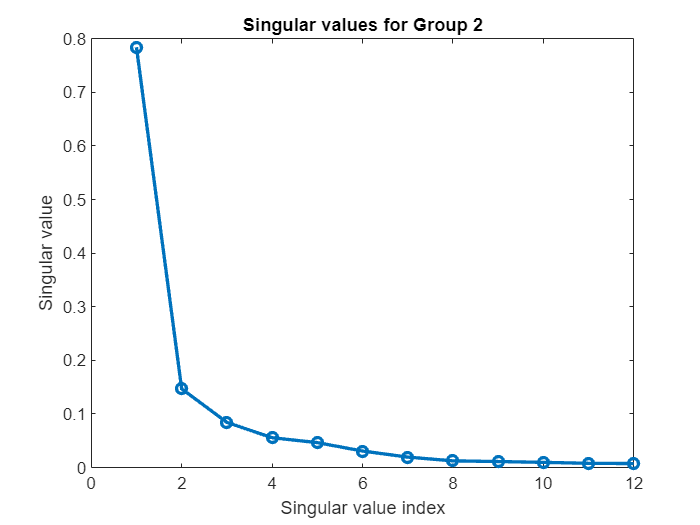

% SVD and visualization for Group 2
[U2, S2, V2] = svd(Group2);
figure;
plot(diag(S2), 'o-', 'LineWidth', 2);
title('Singular values for Group 2');
xlabel('Singular value index');
ylabel('Singular value');

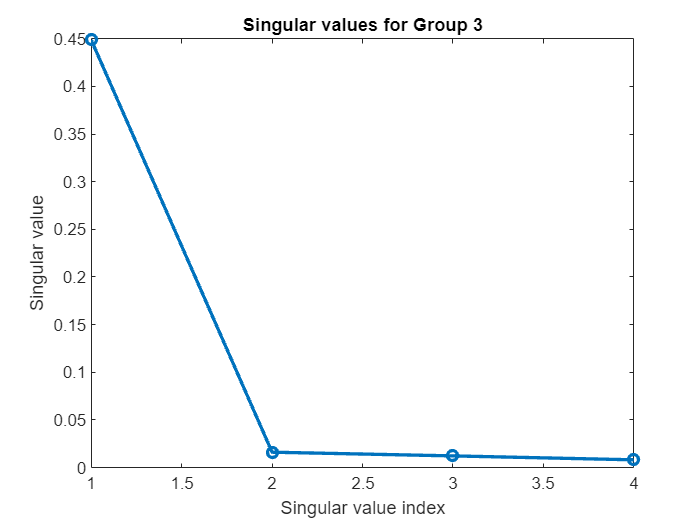


% SVD and visualization for Group 3
[U3, S3, V3] = svd(Group3);
figure;
plot(diag(S3), 'o-', 'LineWidth', 2);
title('Singular values for Group 3');
xlabel('Singular value index');
ylabel('Singular value');


% c)
%%%%%%%%%%%%%%%%%%%%GROUP1%%%%%%%%%%%%%%%%%%%%%%%
%Group1 Rank 2
G1R2 = U1(:,1:2) * S1(1:2,1:2) * V1(:,1:2)';
G1R2V = U1(:,1:2) * S1(1:2,1:2);


%Group1 RANK 3
G1R3 = U1(:,1:3) * S1(1:3,1:3) * V1(:,1:3)';
G1R3V = U1(:,1:3) * S1(1:3,1:3);

%%%%%%%%%%%%%%%%%%%%GROUP2%%%%%%%%%%%%%%%%%%%%%%%
%Group2 Rank 2
G2R2 = U2(:,1:2) * S2(1:2,1:2) * V2(:,1:2)';
G2R2V = U2(:,1:2) * S2(1:2,1:2);


%Group2 RANK 3
G2R3 = U2(:,1:3) * S2(1:3,1:3) * V2(:,1:3)';
G2R3V = U2(:,1:3) * S2(1:3,1:3);

%%%%%%%%%%%%%%%%%%%%GROUP3%%%%%%%%%%%%%%%%%%%%%%%
%Group3 Rank 2
G3R2 = U3(:,1:2) * S3(1:2,1:2) * V3(:,1:2)';
G3R2V = U3(:,1:2) * S3(1:2,1:2);


%Group3 RANK 3
G3R3 = U3(:,1:3) * S3(1:3,1:3) * V3(:,1:3)';
G3R3V = U3(:,1:3) * S3(1:3,1:3);


%%%CODE FOR GETTING NAMES IN PLOT

Group1_tit = {};
Group2_tit = {};
Group3_tit = {};

for i = 1:size(D2inV, 1)
    %%%%
    if D2inV(i, 1) < -0.18
      Group1_tit = [Group1_tit, article_title{i}];
    elseif D2inV(i, 1) > -0.18
        
        if D2inV(i, 2) > 0.1
        Group2_tit = [Group2_tit, article_title{i}];
        else
            Group3_tit = [Group3_tit, article_title{i}];
        end

    end
end


%%Tanspose so its more like a list
Group1_tit = Group1_tit'

Group1_tit = 64×1 cell array
    {'London'    }
    {'Madrid'    }
    {'Oslo'      }
    {'Berlin'    }
    {'Paris'     }
    {'Ankara'    }
    {'Rome'      }
    {'Vienna'    }
    {'Stockholm' }
    {'Warsaw'    }
    {'Helsinki'  }
    {'Tallinn'   }
    {'Lisbon'    }
    {'Bucharest' }
    {'Amsterdam' }
    {'Brussels'  }
    {'Prague'    }
    {'Budapest'  }
    {'Bern'      }
    {'Copenhagen'}
    {'Bratislava'}
    {'Dublin'    }
    {'Zagreb'    }
    {'Sarajevo'  }
    {'Kishinev'  }
    {'Tirana'    }
    {'Vilnius'   }
    {'Ljubljana' }
    {'Riga'      }
    {'Luxembourg'}


Group2_tit = Group2_tit'

Group2_tit = 12×1 cell array
    {'Moscow'        }
    {'Belgrade'      }
    {'Kyiv'          }
    {'Minsk'         }
    {'Sofia'         }
    {'Skopje'        }
    {'Russia'        }
    {'Serbia'        }
    {'Ukraine'       }
    {'Belarus'       }
    {'Bulgaria'      }
    {'NorthMacedonia'}


Group3_tit = Group3_tit'

Group3_tit = 4×1 cell array
    {'Athens' }
    {'Nicosia'}
    {'Greece' }
    {'Cyprus' }


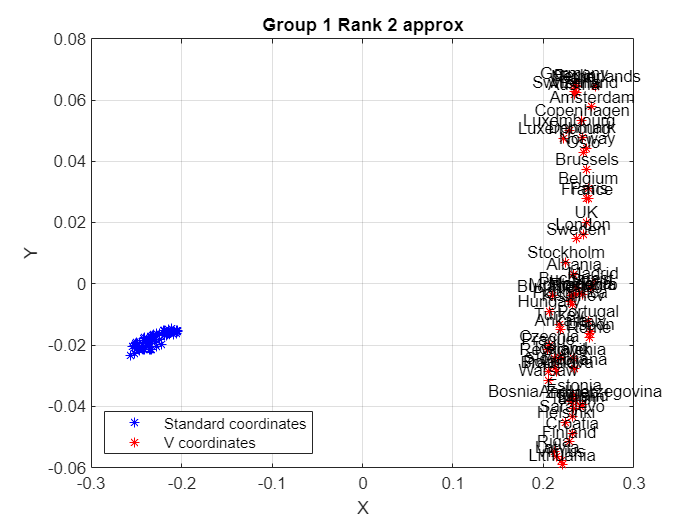

%%%%%%%%%%%%%%%%%%%%GROUP1%%%%%%%%%%%%%%%%%%%%%%%

%Group1 RANK 2 VISUALIZATION
figure
plot (G1R2(:,1), G1R2(:,2), 'b*'),hold on, grid on

plot (G1R2V(:,1), G1R2V(:,2), 'r*');
for i = 1:size(G1R2V, 1)
    text(G1R2V(i, 1), G1R2V(i, 2), Group1_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

title('Group 1 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

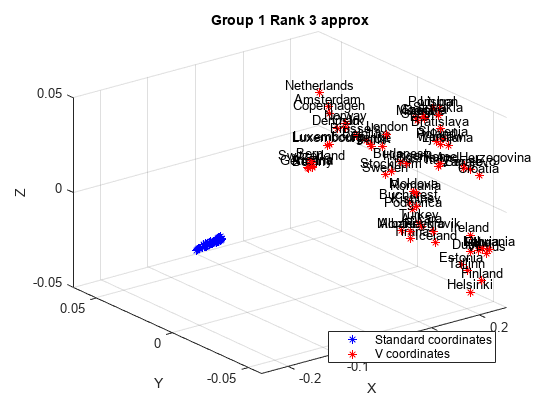

%Group1 RANK 3 VISUALIZATION
figure
scatter3(G1R3(:,1), G1R3(:,2),G1R3(:,3), 'b*'),hold on, grid on
scatter3(G1R3V(:,1), G1R3V(:,2), G1R3V(:,3), 'r*');
for i = 1:size(G1R3V, 1)
    text(G1R3V(i, 1), G1R3V(i, 2), G1R3V(i, 3), Group1_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('Group 1 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

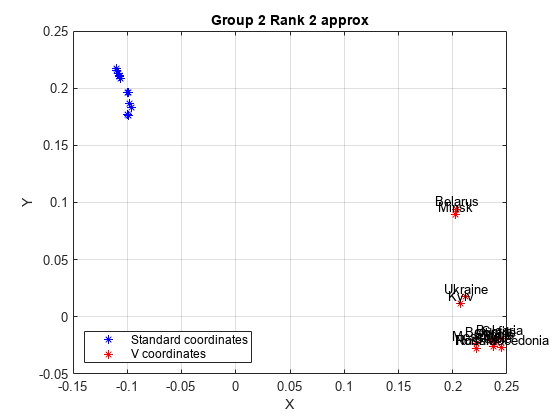

%%%%%%%%%%%%%%%%%%%%GROUP2%%%%%%%%%%%%%%%%%%%%%%%
%Group2 RANK 2 VISUALIZATION
figure
plot (G2R2(:,1), G2R2(:,2), 'b*'),hold on, grid on
plot (G2R2V(:,1), G2R2V(:,2), 'r*');
for i = 1:size(G2R2V, 1)
    text(G2R2V(i, 1), G2R2V(i, 2), Group2_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('Group 2 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

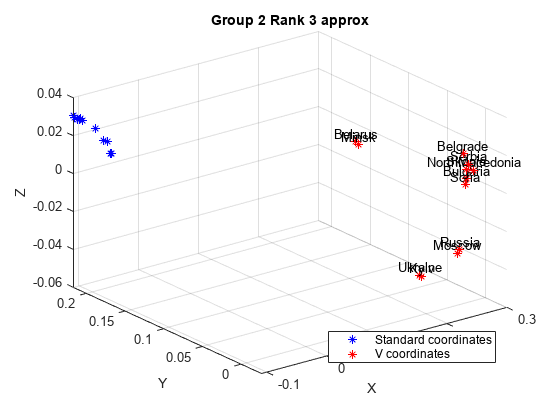

%Group2 RANK 3 VISUALIZATION
figure
scatter3(G2R3(:,1), G2R3(:,2),G2R3(:,3), 'b*'),hold on, grid on
scatter3(G2R3V(:,1), G2R3V(:,2), G2R3V(:,3), 'r*');
for i = 1:size(G2R3V, 1)
    text(G2R3V(i, 1), G2R3V(i, 2), G2R3V(i, 3), Group2_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('Group 2 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

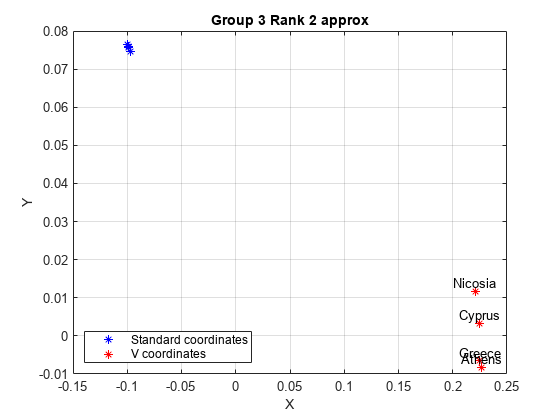

%%%%%%%%%%%%%%%%%%%%GROUP3%%%%%%%%%%%%%%%%%%%%%%%
figure
plot (G3R2(:,1), G3R2(:,2), 'b*'),hold on, grid on
plot (G3R2V(:,1), G3R2V(:,2), 'r*');
for i = 1:size(G3R3V, 1)
    text(G3R2V(i, 1), G3R2V(i, 2), Group3_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('Group 3 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

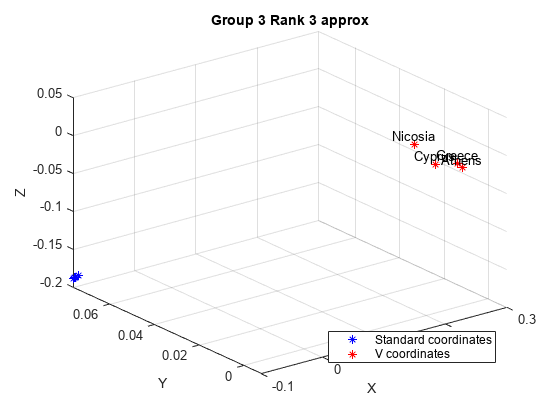

%Group2 RANK 3 VISUALIZATION
figure
scatter3(G3R3(:,1), G3R3(:,2),G3R3(:,3), 'b*'),hold on, grid on
scatter3(G3R3V(:,1), G3R3V(:,2), G3R3V(:,3), 'r*');
for i = 1:size(G3R3V, 1)
    text(G3R3V(i, 1), G3R3V(i, 2), G3R3V(i, 3), Group3_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('Group 3 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

2.2.3) Now for some final reflections:

**Q: **What have you learned while doing this assignment (about the SVD, about languages, ...)?

**Answer: **

- **Have learned that there is mainly 3 different groups of characters/written languages in europe being latin characters, cyrillic and greek.**

- **Learned that it is possible to use the SVD to get a lot of info with low rank apporximation without a big loss of information.**

- **Learned how to visualize big data with and withour low rank approximation, was fun to see that the groupings found before the svd stayed consistent after the svd was perfomed aswell.**

- **Learned that while a rank 2 approximation can convey a lot of info, that we often need to look at rank 3 or higher approximation before we can draw conclutions about the data.**

**Q: **For which problems would you apply this method (which problems can be solved using SVD)? What about the type of data, can this method be used for any type of data? Give some examples of both appropriate and - if you think it cannot be used for all types of data - inappropriate data (you do not have to find actual data sets, just come up with realistic scenarios).

**Answer: **

**SVD seems to be usefull for data that has high dimensionality and where we can use a low rank approximation to get meaningfull insights without huge loss of information. Some examples of this include:**

- **SVD can be used on for example image processing, like on for example the MNIST handwritten numbers where the numbers are presented as a matrix, we could use the svd to forexample compress the image.**

- **Since it can be used for image processing it could also work well on signal processing to compress or reduce noise.**

- **Dimensionality reduction and model simplification by eliminating redundant or insignifficant variables or parameters.**

**The SVD would rewqure that the data is represented in matrix form and that the matrix does not have extreme outliers or missing data. Some data that would not fit the svd would be:**

- **Graph data (for example data on airline destination and origin). **

- **Time series data like for example cryprto prices that change hourly or daily.**